%read path
clear
clc
path = 'C:\Users\thamr\OneDrive\Desktop\finalMatlab\dataset-3a.xlsx';
Q1a = readmatrix(path,'Sheet','Q1A');
QHS1 = readmatrix(path,'Sheet','QH_S1');
QHS3 = readmatrix(path,'Sheet','QH_S3');

hData3 = QHS3(:,1);
qData3 = QHS3(:,2);
y = hData3';
x = qData3';

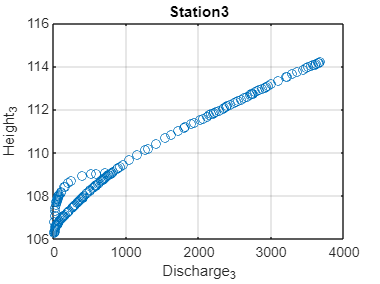

%พอตค่าที่เก็บไว้
hold off
plot(x,y,'o');
xlabel("Discharge_3")
ylabel("Height_3")
title("Station3")
grid on

 %neural network model = md
    hLS = 30;
    net = feedforwardnet(hLS);
    mdl = train(net,x,y);
    nv = mdl(x);

hold on
plot(x,nv,'-','Color','r')
v = y;
% R squared 
R_squared = 1 - sum((v - nv).^2) / sum((v - mean(v)).^2);
% Mean Absolute Error (MAE) calculation
MAE = sum(abs(v - nv))/length(v);
% Mean Squared Error (MSE) calculation
MSE = (sum((v - nv).^2))/(length(v));
fprintf("R_squared : %.5f",R_squared);

R_squared : 0.98116

fprintf("MSE : %.4f",MSE);

MSE : 0.0930

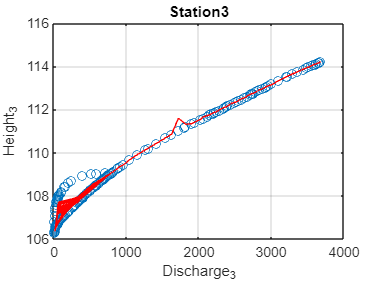

hold off

gUrl = 'http://192.168.1.143:5000/getdatawaterlv/Discharge_S3/60'; 
H1aTest = webread(gUrl); %Q3

H1aTest = H1aTest.Discharge_S3';
H1aTest = H1aTest(~isnan(H1aTest));
for i=1:length(H1aTest)
     predict = sim(mdl,H1aTest);
end
predict = predict(~isnan(predict))';

%เขียนลง Sever
xlswrite(path,predict,1,'H2');

for i=1:length(predict)
    data = predict(i);
    url = 'http://192.168.1.143:5000/senddatah/';
    url = [url,num2str(data)];
    response = webread(url); 
    fprintf("SendH3 Done %d %s\n",i,response)
end

Done 1 OKDone 2 OKDone 3 OKDone 4 OKDone 5 OKDone 6 OKDone 7 OKDone 8 OKDone 9 OKDone 10 OKDone 11 OKDone 12 OKDone 13 OKDone 14 OKDone 15 OKDone 16 OKDone 17 OKDone 18 OKDone 19 OKDone 20 OKDone 21 OKDone 22 OKDone 23 OKDone 24 OKDone 25 OKDone 26 OKDone 27 OKDone 28 OKDone 29 OKDone 30 OKDone 31 OKDone 32 OKDone 33 OKDone 34 OKDone 35 OKDone 36 OKDone 37 OKDone 38 OKDone 39 OKDone 40 OKDone 41 OKDone 42 OKDone 43 OKDone 44 OKDone 45 OKDone 46 OKDone 47 OKDone 48 OKDone 49 OKDone 50 OKDone 51 OKDone 52 OKDone 53 OKDone 54 OKDone 55 OKDone 56 OKDone 57 OKDone 58 OKDone 59 OKDone 60 OK

SendQ3 DONE OK 1
SendQ3 DONE OK 2
SendQ3 DONE OK 3
SendQ3 DONE OK 4
SendQ3 DONE OK 5
SendQ3 DONE OK 6
SendQ3 DONE OK 7
SendQ3 DONE OK 8
SendQ3 DONE OK 9
SendQ3 DONE OK 10
SendQ3 DONE OK 11
SendQ3 DONE OK 12
SendQ3 DONE OK 13
SendQ3 DONE OK 14
SendQ3 DONE OK 15
SendQ3 DONE OK 16
SendQ3 DONE OK 17
SendQ3 DONE OK 18
SendQ3 DONE OK 19
SendQ3 DONE OK 20
SendQ3 DONE OK 21
SendQ3 DONE OK 22
SendQ3 DONE OK 23
SendQ3 DONE OK 24
SendQ3 DONE OK 25
SendQ3 DONE OK 26
SendQ3 DONE OK 27
SendQ3 DONE OK 28
SendQ3 DONE OK 29
SendQ3 DONE OK 30
SendQ3 DONE OK 31
SendQ3 DONE OK 32
SendQ3 DONE OK 33
SendQ3 DONE OK 34
SendQ3 DONE OK 35
SendQ3 DONE OK 36
SendQ3 DONE OK 37
SendQ3 DONE OK 38
SendQ3 DONE OK 39
SendQ3 DONE OK 40
SendQ3 DONE OK 41
SendQ3 DONE OK 42
SendQ3 DONE OK 43
SendQ3 DONE OK 44
SendQ3 DONE OK 45
SendQ3 DONE OK 46
SendQ3 DONE OK 47
SendQ3 DONE OK 48
SendQ3 DONE OK 49
SendQ3 DONE OK 50
SendQ3 DONE OK 51
SendQ3 DONE OK 52
SendQ3 DONE OK 53
SendQ3 DONE OK 54
SendQ3 DONE OK 55
SendQ3 DONE OK 56
S

  hold off

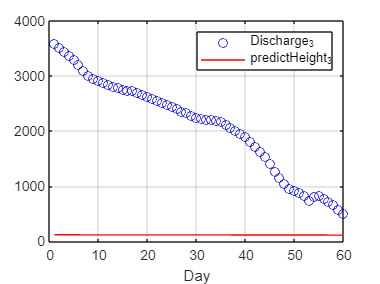

  Q1a = readmatrix(path);
  yTest = Q1a(:,5);
  yTest = yTest(~isnan(yTest))';
  Day = 1:length(yTest);
  plot(Day,yTest,'o',Color='b')
  hold on
  xlabel("Day")
  ylabel("Discharge_3")
  legend("Discharge_3")
  plot(Day,predict','-',Color='r')
  xlabel("Day")
  ylabel("")
  grid on
  legend("Discharge_3","predictHeight_3")

  disp("DONE")

DONE


  % nvAfter = predict(~isnan(predict));
  % vAfter = yTest;
  % % R squared 
  % R_squared_test = 1 - sum((vAfter - nvAfter).^2) / sum((vAfter - mean(vAfter)).^2);
  % % Mean Absolute Error (MAE) calculation
  % MAE_test = sum(abs(vAfter - nvAfter))/length(vAfter);
  % % Mean Squared Error (MSE) calculation
  % MSE_test = (sum((vAfter - nvAfter).^2))/(length(vAfter));
  % fprintf("R_squared predict : %.5f",R_squared_test);
  % fprintf("MSE predict : %.4f",MSE_test);
